format long
N = 400; % Number of independent Bernoulli Trials
x = 0:400; % Number of Successes
p = 0.01;

lambda = N*p; %Probability of Success
y = binopdf(x, N, p); %Binomial PDF in-built funrion with parameter x and p

y =    0.017950553275045   0.072527487979981   0.146153877292991   0.195856037584547   0.196350623538044   0.157080498830435   0.104455887269397   0.059387618447536   0.029468856123588   0.012964973737875   0.005120509829807   0.001833791399104   0.000600458631525   0.000181024047422   0.000050545675579   0.000013138471901   0.000003193378587   0.000000728614009   0.000000156598858   0.000000031802639   0.000000006119599   0.000000001118541   0.000000000194641   0.000000000032312   0.000000000005127   0.000000000000779   0.000000000000113   0.000000000000016   0.000000000000002   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.00000000000

z = poisspdf(x, lambda); %Poisson PDF

# Plotting The Probability Against The Bernoulli Trials

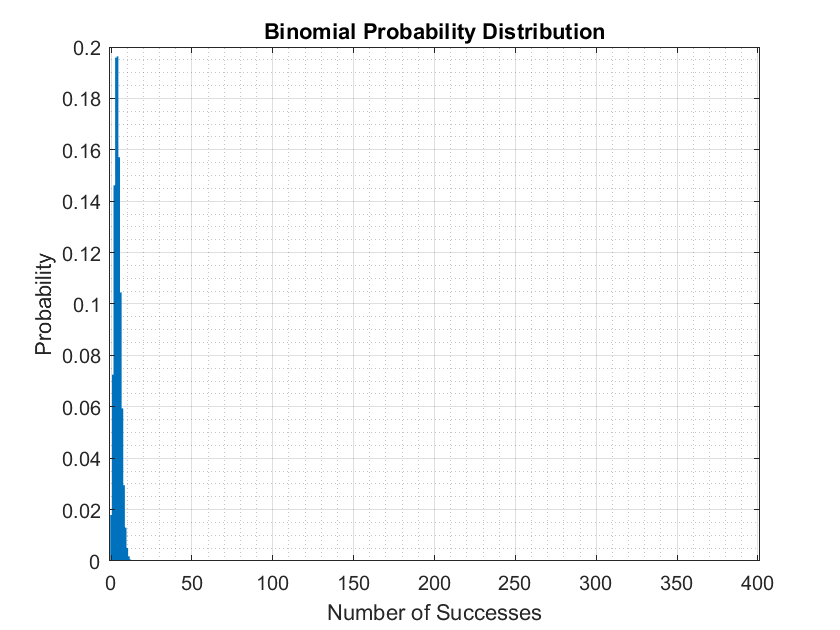

bar(x, y, 1) % Histogram of outputs
grid on; grid minor;
xlabel('Number of Successes')
ylabel('Probability')
title("Binomial Probability Distribution")

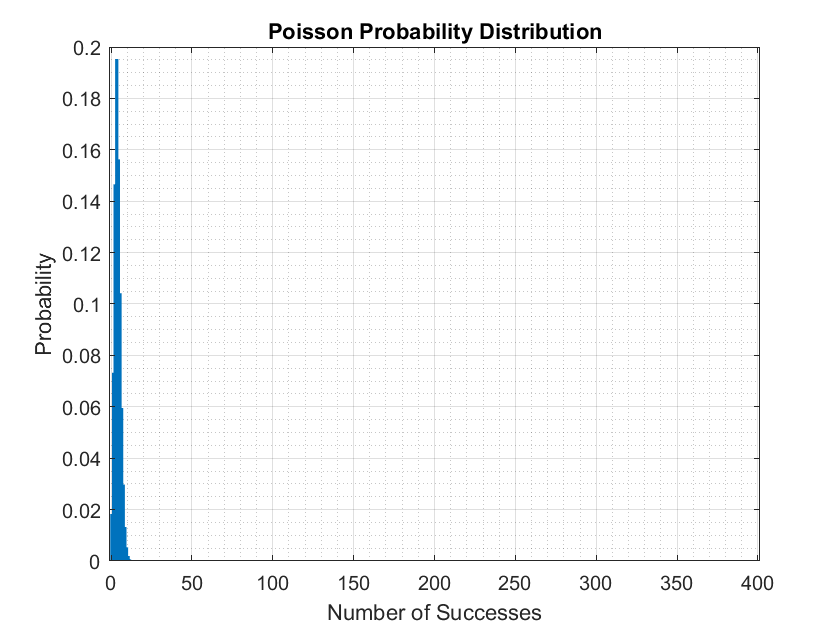



bar(x,z,1)
grid on; grid minor;
title("Poisson Probability Distribution")
xlabel('Number of Successes')
ylabel('Probability')

# Normality Test

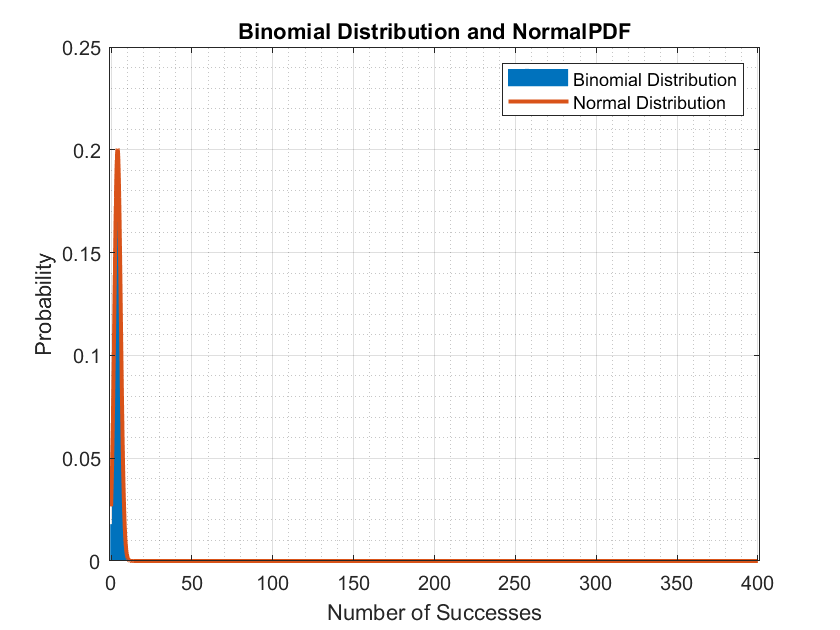

mu = N*p;
sigma = sqrt(mu*(1-p));
x2 = 0:0.1:N;
y2 = normpdf(x2, mu, sigma);
bar(x,y,1)
hold on
plot(x2, y2, 'LineWidth', 2)
xlabel('Number of Successes')
ylabel('Probability')
title('Binomial Distribution and NormalPDF')
grid on; grid minor;
legend('Binomial Distribution','Normal Distribution')
hold off;

# Negative Binomial Probability Distribution

## `A sample question on negative binomial probability `

`A person conducting telephone surveys must get 3 more completed surveys before their job is finished. `

`On each randomly dialed number, there is a 9% chance of reaching an adult who will complete the survey. `

`What is the probability that the 3rd completed survey occurs on the 10th call?`

`Solution`


$$$$ r = 3, p = 0.09, P(X=10) $$$$


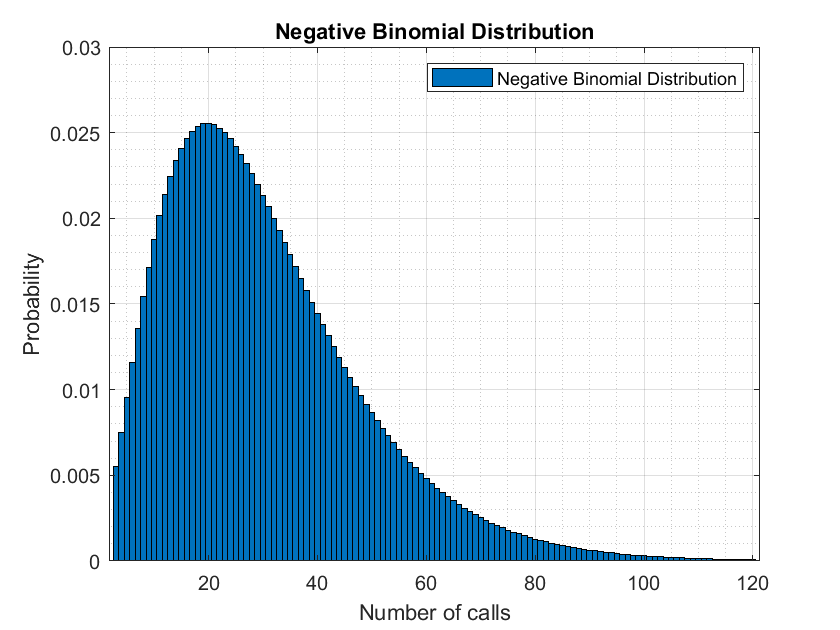


% Set the number of successes required
r = 3;

% Set the probability of success in each Bernoulli trial
p = 0.09;
 
k = 3:120;
y2 = nbinpdf(k, r, p);
bar(k,y2,1);
grid on; grid minor;
legend('Negative Binomial Distribution')
xlabel('Number of calls')
ylabel('Probability')
title('Negative Binomial Distribution')

## `Sample question on negative binomial probability `

`Jim is writing an exam with multiple-choice questions, and his probability of attempting the question with the right answer is 60%. `

`What is the probability that Jim gives the 3rd correct answer for the fifth attempted question?`

`Solution`


$$$$ r = 3, p = 0.6, P(X=5) $$$$


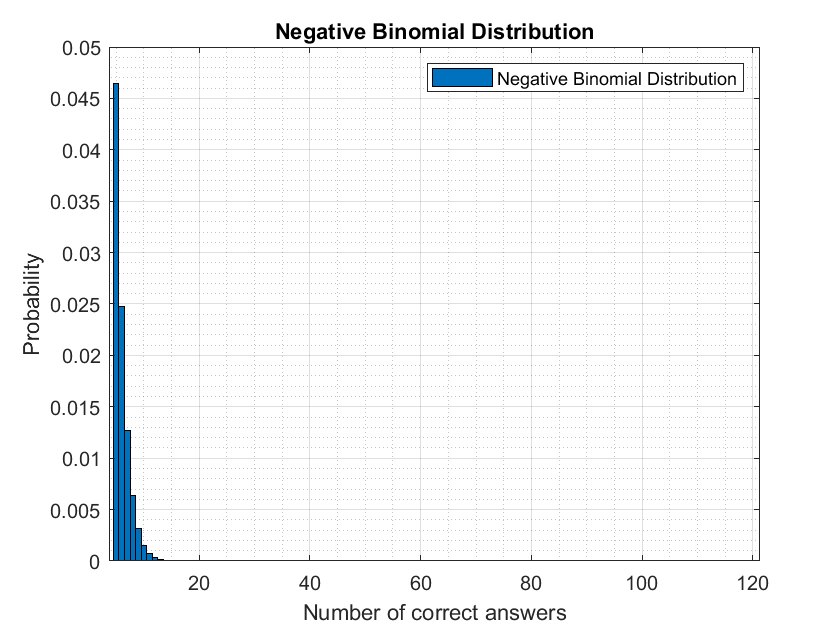

% Set the number of successes required
r1 = 3;

% Set the probability of success in each Bernoulli trial
p1 = 0.6;
 
k1 = 5:120;
y3 = nbinpdf(k1, r1, p1);
bar(k1,y3,1);
% plot(k1, y3, "LineWidth", 2)
grid on; grid minor;
legend('Negative Binomial Distribution')
xlabel('Number of correct answers')
ylabel('Probability')
title('Negative Binomial Distribution')

# Probability Density Function(PDF)


$$\[
f(x) =
\begin{cases}
\frac{1}{4}x, & \text{if } 0\leq  x\leq 2 \\
\frac{x}{4}, &\text{if } 2\leq  x\leq 4 \\
0, & \text{otherwise}
\end{cases}
\]
$$


where $f(x)$ is a probability density function

syms x
f(x) = piecewise((0 <= x) & (x <= 2), (1/4)*x, (2 <= x) & (x <= 4), 1-(1/4)*x,0)

$$f(x) = \left\{ \begin{array}{cl} \frac{x}{4} & \text{ if }x\in \left[0,2\right]\\ 1-\frac{x}{4} & \text{ if }x\in \left[2,4\right]\\ 0 & \mathrm{otherwise} \end{array}\right.$$

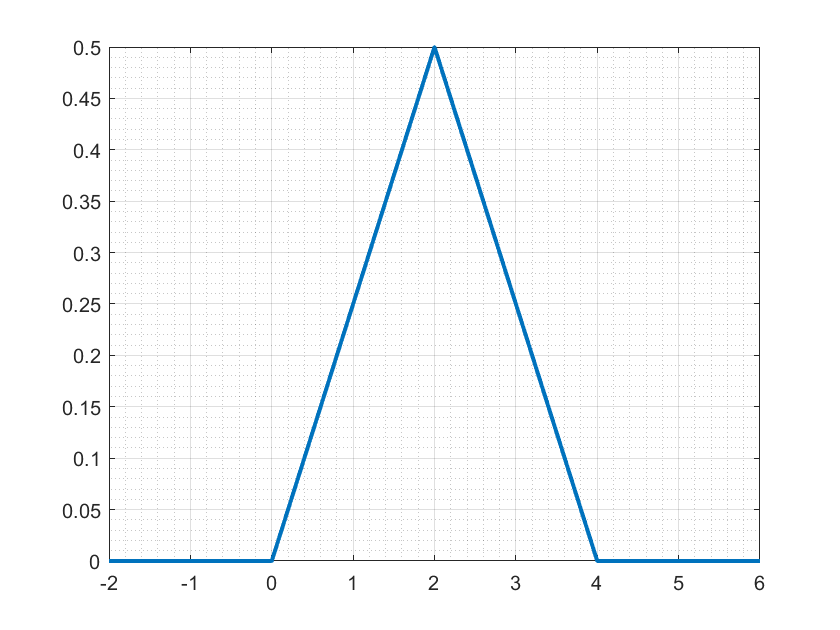

fplot(f,[-2 6], "LineWidth",2);
grid minor; grid on;

## Normal Distribution

pd = makedist('Normal')

pd =   NormalDistribution

  Normal distribution
       mu = 0
    sigma = 1


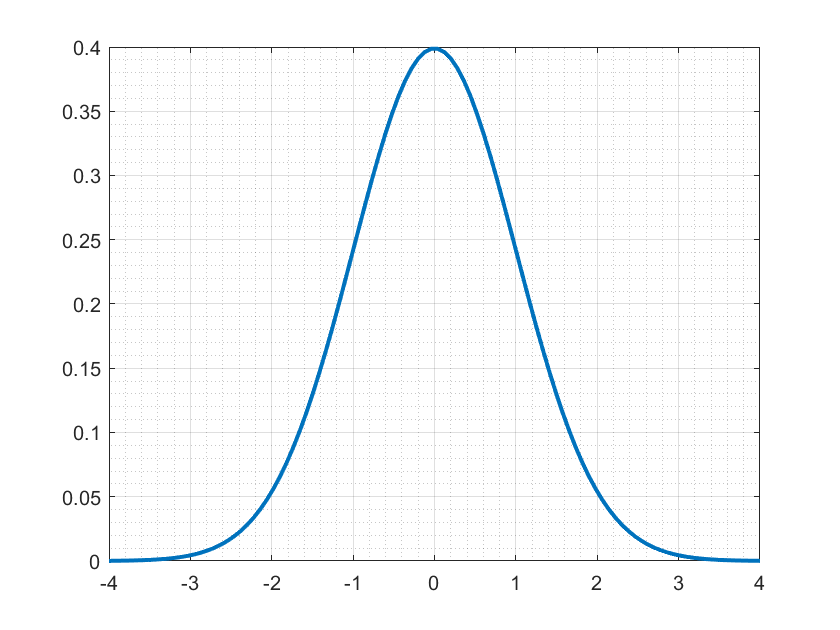

x = linspace(-4, 4, 100);
pdf_normal = pdf(pd,x);
plot(x,pdf_normal,'LineWidth',2);
grid on; grid minor;

## The 90th percentile of a norm distribution

mu = 176.3; % mean of the normal distribution
sigma = 7.1; % standard deviation of the normal distribution
p = 90; % desired percentile

x1 = normrnd(mu, sigma, [1, 1000]); % generate a sample of 1000 values from the normal distribution
% x1 = linspace(150,200,2000);
pctile = prctile(x1, p); % calculate the 90th percentile of the sample

disp(['The ', num2str(p), 'th percentile of the normal distribution is ', num2str(pctile)]);

The 90th percentile of the normal distribution is 185.1086


## Lognormal Distribution

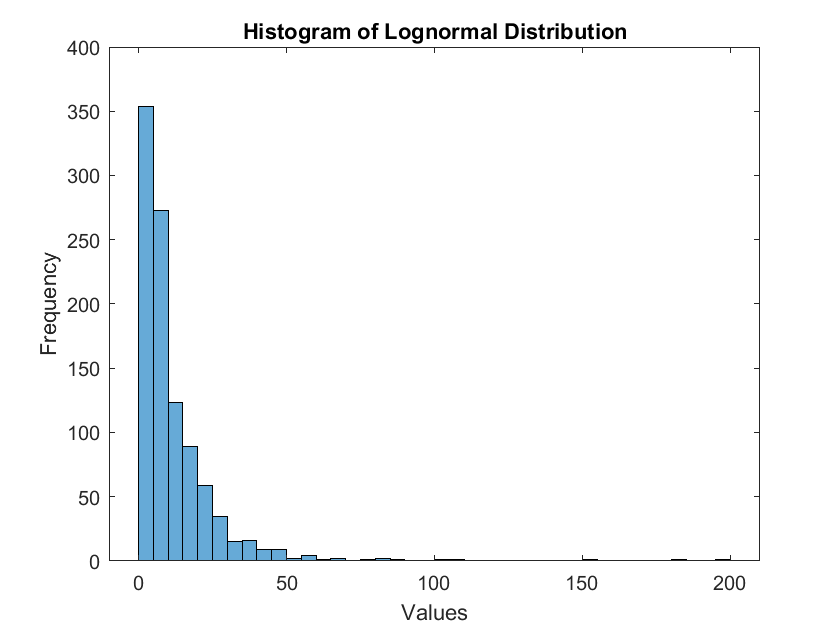

mu = 2; % mean of the lognormal distribution
sigma = 1; % standard deviation of the lognormal distribution
x = lognrnd(mu, sigma, [1000,1]); % generate a sample of 1000 values from the lognormal distribution

histogram(x); % create a histogram of the sample x
title('Histogram of Lognormal Distribution'); % add a title to the histogram
xlabel('Values'); % add a label to the x-axis
ylabel('Frequency'); % add a label to the y-axis
hold off;

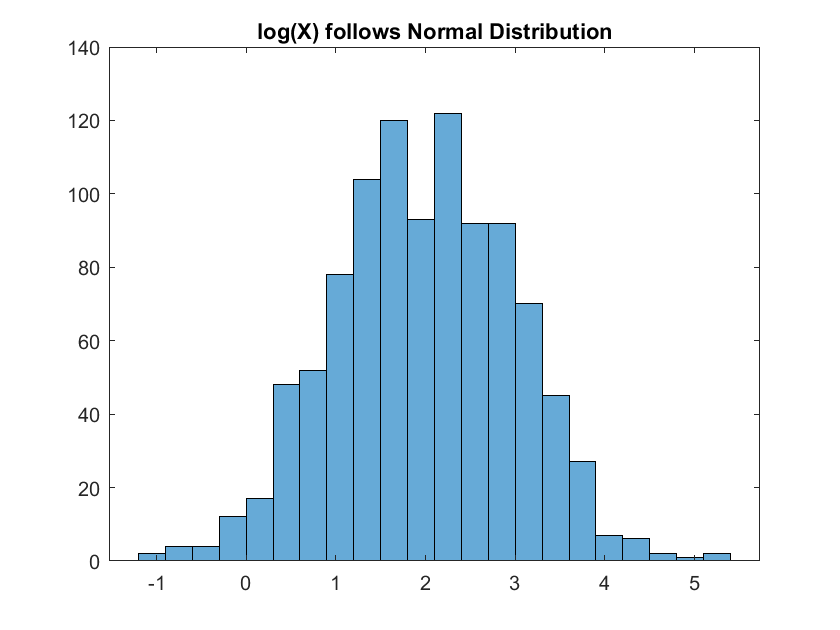


% The natural logarithm of a lognormal distribution has a normal distribution.
histogram(log(x));
title("log(X) follows Normal Distribution")


% side note
% The vertical axis of the histogram is the frequency at which a value
% occurs
count = 0;
for i = 1:size(x,1)
    if (x(i) > 0) && (x(i)<5)
%     disp(x(i));
    count = count + 1;
    end
end
disp(count)

   354



## Beta Distribution

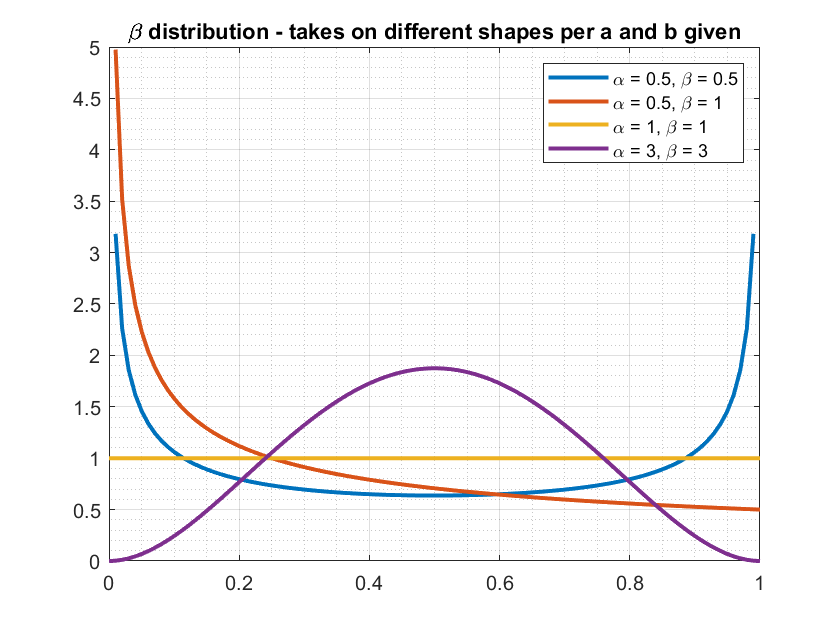

pd_beta = makedist('Beta',"a",0.5,"b",0.5);
x_beta = linspace(0, 1);
pdf_beta = pdf(pd_beta, x_beta);
plot(x_beta, pdf_beta, 'LineWidth',2);
xlim([0 1]);
pd_beta2 = makedist('Beta',"a",0.5,"b",1);
pdf_beta2 = pdf(pd_beta2, x_beta);
hold on;
plot(x_beta, pdf_beta2, 'LineWidth',2);
pd_beta3 = makedist('Beta',"a",1,"b",1);
pdf_beta3 = pdf(pd_beta3, x_beta);
hold on;
plot(x_beta, pdf_beta3, 'LineWidth',2);
pd_beta4 = makedist('Beta',"a",3,"b",3);
pdf_beta4 = pdf(pd_beta4, x_beta);
plot(x_beta, pdf_beta4, 'LineWidth',2);
title("\beta distribution - takes on different shapes per a and b given");
legend("\alpha = 0.5, \beta = 0.5", "\alpha = 0.5, \beta = 1", ...
    "\alpha = 1, \beta = 1", "\alpha = 3, \beta = 3")
grid on; grid minor;
hold off;

## Gamma Distribution

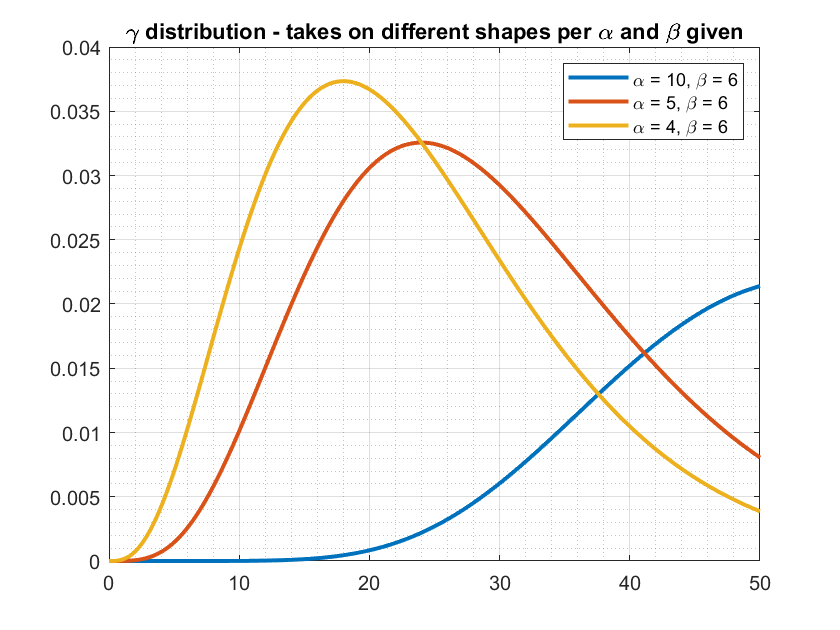

pd_gamma = makedist('Gamma',"a",10,"b",6);
x_gamma = linspace(0, 50, 1000);
pdf_gamma = pdf(pd_gamma, x_gamma);
plot(x_gamma, pdf_gamma, 'LineWidth',2);
xlim([0 50]);
pd_gamma2 = makedist('Gamma',"a",5,"b",6);
pdf_gamma2 = pdf(pd_gamma2, x_gamma);
hold on;
plot(x_gamma, pdf_gamma2, 'LineWidth',2);
pd_gamma3 = makedist('Gamma',"a",4,"b",6);
pdf_gamma3 = pdf(pd_gamma3, x_gamma);
hold on;
plot(x_gamma, pdf_gamma3, 'LineWidth',2);
title("\gamma distribution - takes on different shapes per \alpha " + ...
    "and \beta given");
legend("\alpha = 10, \beta = 6", "\alpha = 5, \beta = 6", ...
    "\alpha = 4, \beta = 6")
grid on; grid minor;
hold off;


max(pdf_gamma)

ans =    0.021396060625033
